# Body Frame of Reference and Rotation Matrices

## Topic

This LiveScript discusses the six-degree-of-freedom model (6DOF) and introduces the topic of Rotation Matrices.

## Motivation

Thus far you analysis of UAV motion has been characterized by the UAV position, oriented parallel to the flat Earth, in an inertial coordinate system.    While this is a great place to start, it does not give you a full description of UAV flight.  For that you have to consider how the UAV is oriented in space.   Is it level to the ground and hence orthoganol to the gravity vector?   Or is it tilted with respect to the ground (and the gravity vector)?   

Beginning in this lesson you will develop a more complete description of UAV flight and for that  you need to describe six degrees of freedome (6DOF).   To accomplish this you will need, in addition to the coordinates $\left(x,y,z\right)$ you need three angles $\left(\theta \;,\phi \;,\psi \right)$.  The process for defining all of this begins with a new coordinate system, called the body reference frame, which is centered at the center of mass of the UAV.

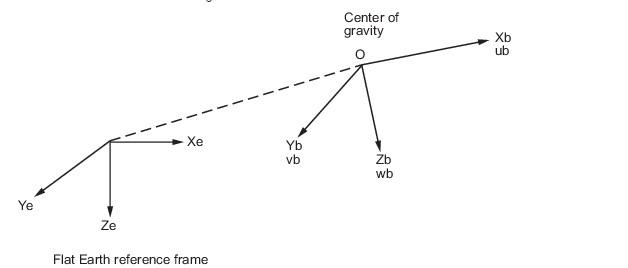

## Learning Objective

In this lesson you will go through the formulation of rotating a rigid body so that you can manipulate the orientation of the UAV airframe model in space.    You will begin with a quick review of the idea of rigid body displacement and then move on to the development of rotation matrices and the concept of a Body Reference Frame.  By the end of this second part of the airframe module, you will be able to:

- Understand the Flat Earth Reference Frame Convention, with the z-axis pointed down.

- Understand the Euler Angles $\left(\theta \;,\phi \;,\psi \right)$

- Understand the Body Reference Frame of your UAV

- Understand the transformation between the Inertial Reference frame and the Body Reference Frame

## Lesson

After you have a basic understanding of Newtonian Dynamics for a point mass, you need to begin to add addiitional features to your model in order to transition from a point mass to a rigid body.     Afterall, you are trying to model a UAV and a UAV is not a point mass.   In particular, the angles describing how the UAV is oriented in space have signfiicant impacts on the motion of the vehicle.    

In your new model, you will keep track of the orientation of the UAV body in space.  That  is in addition to the position and velocity (of the center of mass), you will keep track of the angles that define the orientation of the rigid body (eventually our UAV) with respect to the reference frame defined by the earth.   This gives you three additional parameters to track, so now the total is six.   $\left(x\;,y\;,z\;,\theta \;,\phi \;,\psi \right)$.    Later, you will discover that, like the three degree of freedom model developed in the first part of the lesson, your states will include both the the angles  $\left(\theta \;,\phi \;,\psi \right)$ and their derivatives.    You don't need to worry about that at first.

In this part of your lesson, the key things you will need to understand have to do with rigid body displacement.   You will assume the UAV does not deform as it flies through the air - and for the most part, this is true.

### Flat Earth Reference Frame

The inertial reference frame that you will use throughout the remaining modules in the "Flat Earth Reference Frame".   This is one of the standard reference frames used within the UAV community.  You can read more about it in the MATLAB help for "6DOF".   The flat Earth reference frame is considered inertial, an excellent approximation that allows the forces due to the Earth motion relative to the "fixed stars" to be neglected.

The interesting thing about the flat Earth reference frame that you need to remember is that the z-axis is pointed down.  

In the previous lessons, you defined a cartesian reference frame with the z-axis pointed up and with the gravity vector pointed down.   While that satisfied your intuition with "up" being positive z, **you** **need to change** this now to conform with the standard and the remaining modules.

#### Gravity

In the flat earth reference frame, gravity creates a force on your UAV which, in the flat Earth reference frame, points in the positive ${\hat{a} }_z$ direction.

The gravitational force in your model is represented in the vector $\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
-\textrm{mg}
\end{array}\right\rbrack$ and so, the sign of this force needs to change.

#### Applied Feed-Forward Force

As you refined your airframe model with a desire to command it to hover, you added a feed-forward force to counteract gravity.   Later you will learn how you will implement that force in your UAV, but for now, you need to update the sign convention so that it matches the flat Earth reference frame.

The feed-forward force in your model is represented in the vector  $\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
F_{\textrm{fwd}} 
\end{array}\right\rbrack$ and the magnitude of the force was defined to be $F_{\textrm{fwd}} =\textrm{mg}$.  For reasons that have to do with the implementation, you will want to maintain the vector formulation as is, but change the magnitude of the force in your model.

#### Updated Airframe Model

Your updated airframe model will now take the form


$$\frac{d}{\mathrm{d}t}\left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)\\
z\left(t\right)\\
v_x \left(t\right)\\
v_y \left(t\right)\\
v_z \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)\\
z\left(t\right)\\
v_x \left(t\right)\\
v_y \left(t\right)\\
v_z \left(t\right)
\end{array}\right\rbrack +\frac{1}{m}\left\lbrace \left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
\textrm{mg}
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
F_{\textrm{drag},x} \\
F_{\textrm{drag},y} \\
F_{\textrm{drag},z} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
F_{\textrm{fwd}} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
F_{\textrm{pd}} 
\end{array}\right\rbrack \right\rbrace$$
  

where$\left\lbrack \begin{array}{c}
0\\
0\\
0\\
F_{\textrm{drag},x} \\
F_{\textrm{drag},y} \\
F_{\textrm{drag},z} 
\end{array}\right\rbrack =-k_d \sqrt{{\left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack }\left\lbrack \begin{array}{c}
0\\
0\\
0\\
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack$

with $\left\lbrack \begin{array}{c}
x\left(0\right)\\
y\left(0\right)\\
z\left(0\right)\\
v_x \left(0\right)\\
v_y \left(0\right)\\
v_z \left(0\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_0 \\
y_0 \\
z_0 \\
v_{\textrm{x0}} \\
v_{\textrm{y0}} \\
v_{\textrm{z0}} 
\end{array}\right\rbrack$

and your feed-forward force will be defined as $F_{\textrm{fwd}} =-\textrm{mg}$ and where your simple PD controller force is $F_{\textrm{pd}} =F_p +F_v$ where $F_p =k_p \left(z_{\textrm{desired}} -z\right)$   and   $F_v =k_v \left(0-v_z \right)$.

### Example

Now, using the flat Earth reference frame, if you want to hover at one meter above the earth, then $z_{\textrm{desired}} =-1$ and your output should look like:

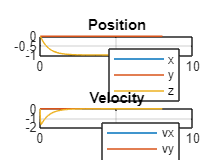

clear
addpath('utils');
params=sys_params;
w0=zeros(12,1);     % For this example, the initial state is zero.
mxyz=[0;0;0];   fxyz=[0;0;0];

tmax=8;
tspan=[0,tmax];

kd=0;
m=params.mass;
g=params.gravity;
ff=-m*g;

kp=6.5;
kv=3.6;
zdesired = -1;


systemDerivative=@(t,w)dwdt(t,w,mxyz,fxyz,kd,ff,kp,kv,zdesired);
[ts,ws]=ode45(systemDerivative,tspan,w0); 
parametric_output3dof(ts,ws)

### Rigid Body Displacement

A rigid body displacement and rotation can be distinguished by two features

- The shape of the body does not deform

- The size of the body does not change

This can be expressed mathematically with the statements

- Orthogonal vectors are mapped to orthogonal vectors

- The transformation preserves inner products

You don't need to worry about this too much, but essentially is says that the dimensions of the object do not change as it moves and rotates.   This simplifies the calculus.   For the purposes of developing your UAV model, it is also useful to remember that as a rigid body moves through the air, its motion can be decomposed into the motion of the center of mass of the UAV and a rotation about the center of mass of the UAV.

### Body Frame and Inertial Coordinate Systems

In part 1, you studied the motion of a mass under the influence of gravity.   One of the first things you will want to do, after understanding gravity and as you build up your UAV model, is consider the forces exerted by the propellers of the UAV.    

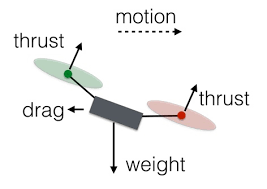

In the figure above, the UAV is moving in the horizontal direction, and gravity is pulling it down in the vertical direction.   The thrust of the UAV propellers exert a force that has components in both.   The orientation of the UAV in the respect to the reference frame of gravity makes a huge difference.    As a result of its own geometry, it is easiest to define the direction of the forces created by the propellers in terms of a coordinate system defined from the center of mass of the UAV.   

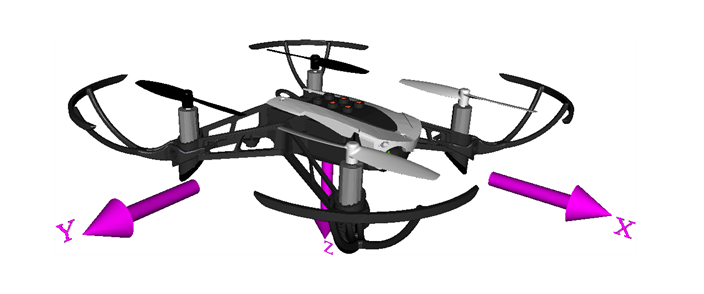

We call this the Body Reference Frame, or simply the Body Frame.     The Body Frame moves with respect to the inertial Earth Frame.   It can be characterized by the position and  velocity of the origin of the Body Frame with respect to the Earth Frame, and by the rotaton of the Body Frame about its own axes.  Just as it is easiest to describe the forces created by the propellers in a reference frame associated with the body of the UAV, it is easiest to define the forces, such as gravity, of the environment in which the UAV is flying in terms of an inertial, fixed, coordinate system.   This is commonly called the Earth Reference Frame or Inertial Frame.

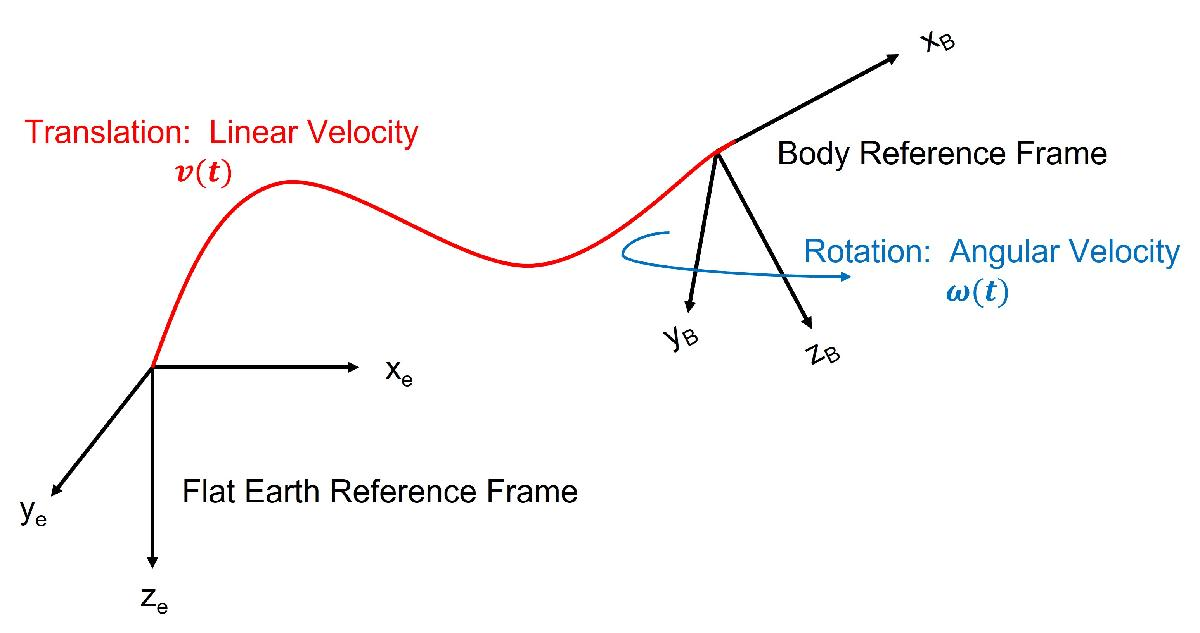

You will need both of these reference frames to be able to track the orientation of our rigid body UAV in a meaningful way.  Therefore you willl need to be able to transform the description of the dynamics between the two.

### Transformations

Let's begin with a simple case of transforming between an inertial frame and a body frame which is just a simple rotation.  (That is, the center of mass does not move.)    We can write one vector, $\vec{\textrm{PQ}}$, in both reference frames.


$$\vec{\textrm{PQ}} =p_1 \;a_1 +p_2 a_2 +p_3 a_3$$



$$\vec{\textrm{PQ}} =q_1 \;b_1 +q_2 b_2 +q_3 b_3$$


where $\left\lbrace a_1 ,a_2 ,a_3 \right\rbrace$ are the set of mutually orthoganol vectors in the one frame of reference and $\left\lbrace b_1 ,b_2 ,b_3 \right\rbrace$ are the set of mutually orthoganol vectors in the another frame of reference.


$$\left\lbrack \begin{array}{c}
b_1 \\
b_2 \\
b_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
R_{11}  & R_{12}  & R_{13} \\
R_{21}  & R_{22}  & R_{23} \\
R_{31}  & R_{32}  & R_{33} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_1 \\
a_2 \\
a_3 
\end{array}\right\rbrack$$


### Rotation Matrices

The rotational matrices are deposed into three separate rotations.

$R_{\textrm{YZ}} =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \phi  & -\sin \phi \\
0 & \sin \phi  & \cos \phi 
\end{array}\right\rbrack$    this is called ROLL and is a rotation about the x-axis

$R_{\textrm{ZX}} =\left\lbrack \begin{array}{ccc}
\cos \theta  & 0 & \sin \theta \\
0 & 1 & 0\\
-\sin \theta  & 0 & \cos \theta 
\end{array}\right\rbrack$    this is called PITCH and is a rotation about that y-axis

$R_{\textrm{XY}} =\left\lbrack \begin{array}{ccc}
\cos \psi  & -\sin \psi  & 0\\
\sin \psi  & \cos \psi  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$     this is called YAW and is rotation about the z-axis

The combined rotation is the matrix product of each of these rotations.


$$R=R\left(\theta ,\phi ,\psi \right)=R_{\textrm{YZ}} R_{\textrm{ZX}} R_{\textrm{XY}} =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \phi  & -\sin \phi \\
0 & \sin \phi  & \cos \phi 
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
\cos \theta  & 0 & \sin \theta \\
0 & 1 & 0\\
-\sin \theta  & 0 & \cos \theta 
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
\cos \psi  & -\sin \psi  & 0\\
\sin \psi  & \cos \psi  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$
 

Some interesting properties of all rotation matrices, regardless of the angles of rotation are:


$$R^T R=I$$
    
$$\det \left(R\right)=1$$


addpath('utils');

% Euler Angles
phi =  15 ;    % Roll
thta = 0;    % Pitch
psi =  0;     % Yaw


% Rotation Matrices:  Example

RYZ=@(phi) [1           0        0   ;               % ROLL
            0          cosd(phi)   -sind(phi);
            0          sind(phi)  cosd(phi)];


RZX=@(thta) [cosd(thta)     0       sind(thta);      % PITCH
                0           1          0;
             -sind(thta)    0        cosd(thta)];


RXY=@(psi)  [cosd(psi)      -sind(psi)      0;        % YAW
             sind(psi)      cosd(psi)       0;        
                0               0           1];


R=RYZ(phi)*RZX(thta)*RXY(psi);


disp("Rotation Matrix R")

Rotation Matrix R


disp(R)

    1.0000         0         0
         0    0.9659   -0.2588
         0    0.2588    0.9659



disp("determinant of R: ")

determinant of R: 


disp(det(R))

    1.0000



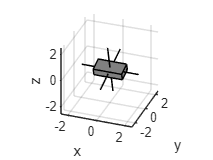


% Visualize Rotating a Box (Rigid Body)
RotateBoxPlot(phi,thta,psi);

## Conclusion

In this section, you added to your development of the equations of motion for the CoM of the UAV in the reference frame of the fixed (inertial) earth.  In particular, you developed an understanding of the rotation matrices so that you can begin to relate the inertial reference frame with a reference frame that is centered about the body of the UAV and which will often rotate with respect to the fixed earth.    You will be able to use these matrices in the next lesson and develop the equations of motion of this 6DOF UAV and thereby bring everything together to fully describe the UAV dynamics.

## Exercises

### Part A.   Update Model to use standard convention 

- Update the gravitational force and feed-forward terms in your UAV model to conform with the conventional Flat-Earth reference frame where the gravity vector points in the positive z direction.

### Part B.   Manipulation

- Can you manipulate the pitch, roll, and yaw of the rigid body and confirm your expectations?

- Now try to systematically begin by changing the yaw, then the pitch and then the roll.  Does the motion of the body make more intuitive sense?    

- As you make changes, in a UAV Body Frame, typically z is associated with altitude and x is associated with forward movement.   Is this consistent with your understand of what UAV pitch, roll and yaw do?

### Part C.  Creation of Rotation Function

- In the forthcoming lessons, you will need  a function to generate the rotation matrix as a function of the Euler Angles.  Create that function now and compare your results with those calculated in this lesson.

% Your code goes here.

